dataset preparation

[dataset_train,dataset_val,dataset_test] = prepdataset();

network definition and training

% DEFINE NETWORK HERE


net = trainnet(dataset_train.sequences, dataset_train.labels, layers, "crossentropy", options)

evaluation

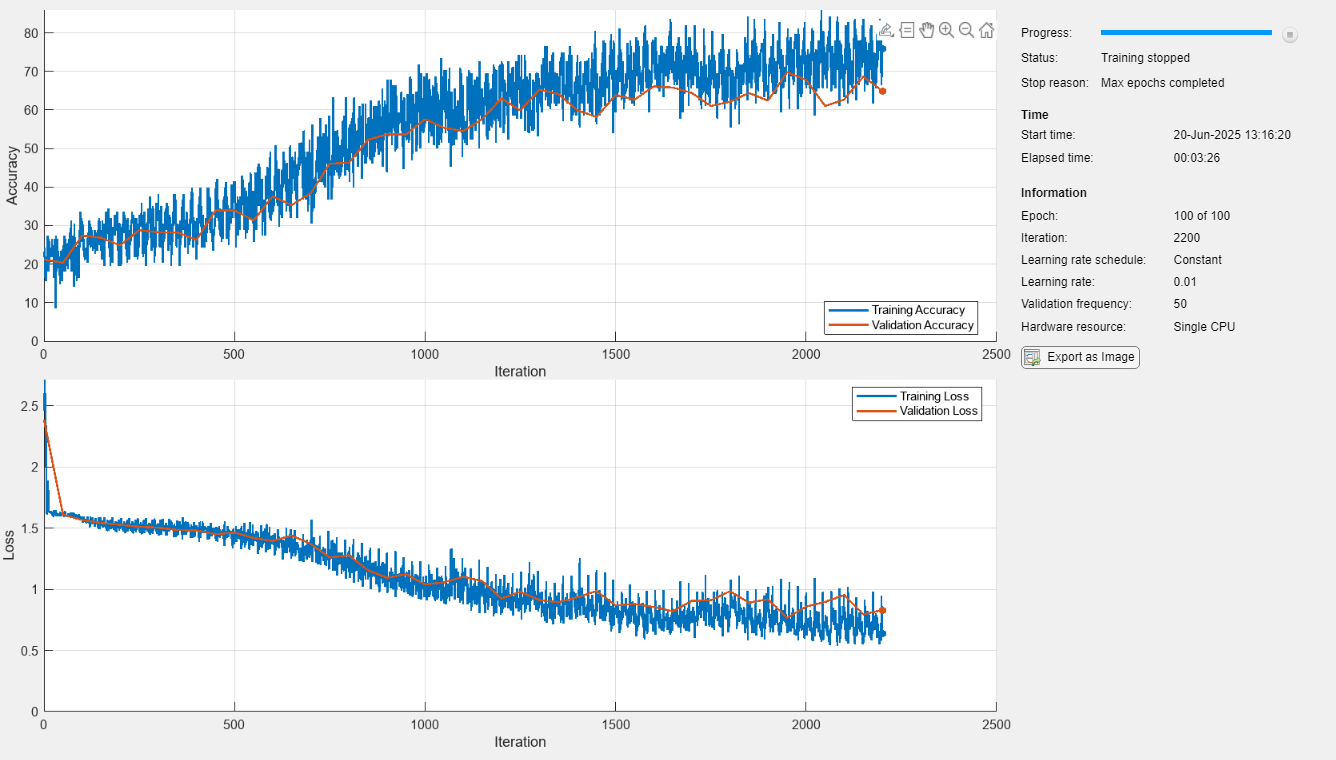

net =   dlnetwork with properties:

         Layers: [10×1 nnet.cnn.layer.Layer]
    Connections: [9×2 table]
     Learnables: [10×3 table]
          State: [0×3 table]
     InputNames: {'sequenceinput'}
    OutputNames: {'softmax'}
    Initialized: 1

  View summary with summary.


accuracy_val = eval(net, dataset_val)

accuracy_test = eval(net, dataset_test)

function accuracy = eval(net, dataset)

accuracy_val = 0.6497

    xtestcell = dataset.sequences;

accuracy_test = 0.6591

    ytest = dataset.labels;
    numsamples = numel(xtestcell);
    xtestarr = zeros(2, numsamples, 128, 'single');
    
    for i = 1:numsamples
        seq = xtestcell{i};
        xtestarr(:, i, :) = permute(single(seq), [2 3 1]);
    end
    dlxtest = dlarray(xtestarr, 'CBT');
    dlypred = predict(net, dlxtest);
    
    [~, idx] = max(extractdata(dlypred), [], 1);
    
    classes = categories(ytest);
    ypred = categorical(classes(idx), classes);
    
    accuracy = mean(ypred == ytest);
end